Stabilità

clear

q_point = [8e-3 3]; %Ic VCE
op_freq = 5e9;
lin_freq = 0.5e9:10e6:6e9;

Z0=50; %ohm

bfp640 = read(rfckt.amplifier , 'BFP640/BFP640_w_noise_VCE_3.0V_IC_8.0mA.s2p');
[s_par , freq] = extract(bfp640 , 'S_parameters');

L-Matching

Input match

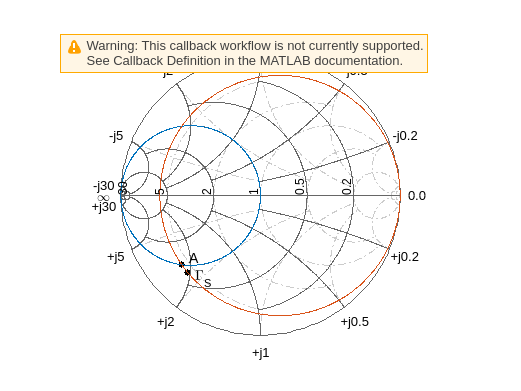


AllGammaS = calculate(bfp640,'GammaMS','none');

gammas = AllGammaS{1}(freq == op_freq);

figure
sp = smithplot;
sp.GridType = 'YZ';

Za = (0.162-0.367j)*Z0;

circle(bfp640 , op_freq , "G" , 1 , "R", real(gamma2z(gammas , 1)) , sp);
hold on
plot(gammas,'k.','MarkerSize',16);
text(real(gammas)+0.05,imag(gammas)-0.05,'\Gamma_{S}','FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Za),'k.','MarkerSize',16);
text(real(z2gamma(Za))+0.05,imag(z2gamma(Za))+0.05,'A','FontSize', 12, ...
    'FontUnits','normalized');
hold off


C_shunt = imag(1/Za)/(2*pi*op_freq)

C_shunt = 1.4518e-12

C_series = 1/(2*pi*op_freq*abs(imag(gamma2z(gammas) - Za)))

C_series = 1.1415e-11



input_match = rfckt.cascade('Ckts', ...
    {rfckt.shuntrlc('C',C_shunt),rfckt.seriesrlc('C',C_series)});

Output match

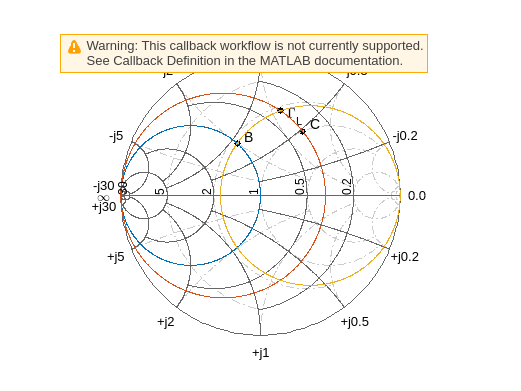

AllGammaL = calculate(bfp640,'GammaML','none');
gammal = AllGammaL{1}(freq == 5e9);

figure
sp2 = smithplot;
sp2.GridType = 'YZ';

Zb = (0.555+0.496j)*Z0;
Zc = (0.993+1.317j)*Z0;

circle(bfp640 , op_freq , "G" , 1 , "G" , real(1/gamma2z(gammal , 1)) , "R", real(gamma2z(gammal , 1)) , sp2);
hold on
plot(gammal,'k.','MarkerSize',16);
text(real(gammal)+0.05,imag(gammal)-0.05,['\Gamma_{L}'],'FontSize', 12, ...
    'FontUnits','normalized');

plot(z2gamma(Zb),'k.','MarkerSize',16);
text(real(z2gamma(Zb))+0.05,imag(z2gamma(Zb))+0.05,'B','FontSize', 12, ...
    'FontUnits','normalized');
plot(z2gamma(Zc),'k.','MarkerSize',16);
text(real(z2gamma(Zc))+0.05,imag(z2gamma(Zc))+0.05,'C','FontSize', 12, ...
    'FontUnits','normalized');
hold off


% L_shunt = 1/(abs(imag(1/Zb)*2*pi*op_freq))
% L_series = abs(imag(gamma2z(gammal) - Zb))/(2*pi*op_freq)
% output_match = rfckt.cascade('Ckts', ...
%     {rfckt.seriesrlc('L',L_series),rfckt.shuntrlc('L',L_shunt)});


L_shunt = 50/abs(imag(gamma2z(gammal,1) - Zc/50))/(2*pi*op_freq)

L_shunt = 7.3613e-09


abs(imag(Zc))

ans = 65.8500

L_series = abs(imag(Zc))/(2*pi*op_freq)

L_series = 2.0961e-09

output_match = rfckt.cascade('Ckts', ...
  {rfckt.shuntrlc('L',L_shunt),rfckt.seriesrlc('L',L_series)});

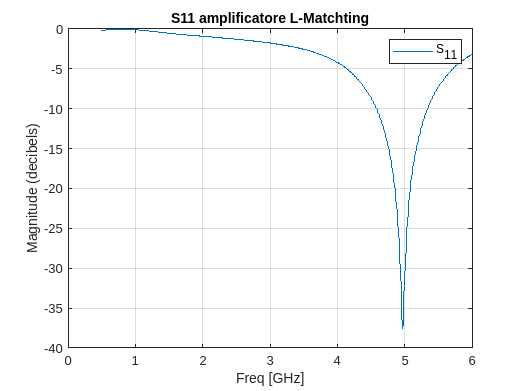

LNA = rfckt.cascade('ckts', ...
    {input_match,bfp640,output_match});

analyze(LNA,lin_freq);

figure,plot(LNA,'S11','dB');
title("S11 amplificatore L-Matchting")
hold on

hold off

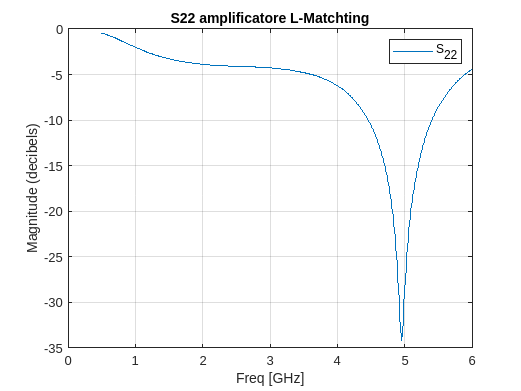


figure,plot(LNA,'S22','dB');
title("S22 amplificatore L-Matchting")
hold off

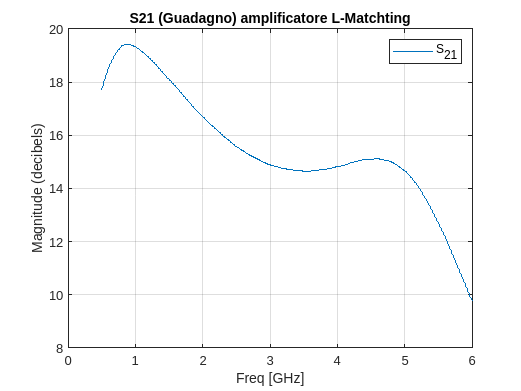


figure,plot(LNA,'S21','dB');
title("S21 (Guadagno) amplificatore L-Matchting")

STUB

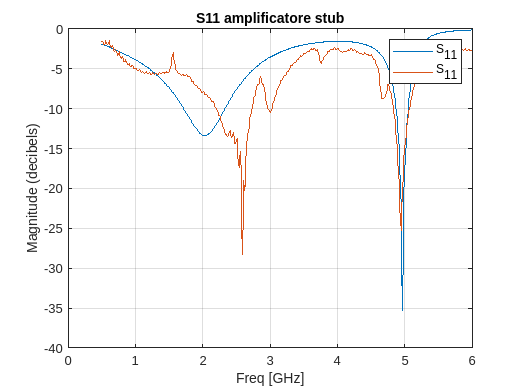




TL1 = rfckt.microstrip('Width',1.7e-3, 'Height',0.8e-3,'EpsilonR',3.66, 'LossTangent',0.0037,...
    'LineLength',6.61e-3,'Thickness',0.0035e-3,'StubMode','Shunt','Termination','Open');
TL2 = rfckt.microstrip('Width',1.7e-3, 'Height',0.8e-3,'EpsilonR',3.66, 'LossTangent',0.0037,...
    'LineLength',17.49e-3,'Thickness',0.0035e-3);


TL3 = rfckt.microstrip('Width',1.7e-3, 'Height',0.8e-3,'EpsilonR',3.66, 'LossTangent',0.0037,...
    'LineLength',7.61e-3,'Thickness',0.0035e-3);

TL4 = rfckt.microstrip('Width',1.7e-3, 'Height',0.8e-3,'EpsilonR',3.66, 'LossTangent',0.0037,...
    'LineLength',5.72e-3,'Thickness',0.0035e-3,'StubMode','Shunt','Termination','Open');

LNA_stub = rfckt.cascade('ckts', ...
    {TL1,TL2,bfp640,TL3,TL4});

analyze(LNA_stub,lin_freq);

LNA_stub_sper = read(rfckt.amplifier , 'LNA-6Volt.s2p');
analyze(LNA_stub_sper,lin_freq);

figure,plot(LNA_stub,'S11','dB');
title("S11 amplificatore stub")
hold on
plot(LNA_stub_sper,"S11")
hold off

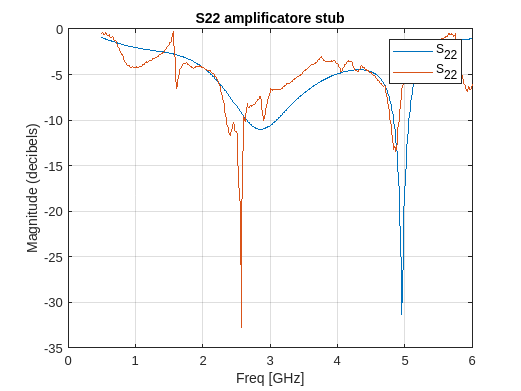



figure,plot(LNA_stub,'S22', 'dB');
title("S22 amplificatore stub")
hold on
plot(LNA_stub_sper,"S22")
hold off

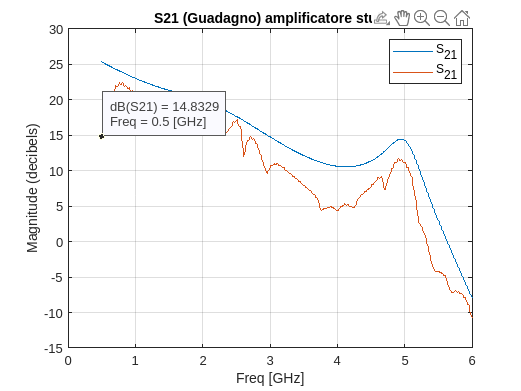


figure,plot(LNA_stub,'S21', 'dB');
title("S21 (Guadagno) amplificatore stub")
hold on
plot(LNA_stub_sper ,'S21', 'dB');
hold off